# **Identifying Igneous Rocks with Ternary Diagrams**

### **Submission for the 2026 MATLAB STEM Showcase**

  Copyright 2026 Austin M. Weber

#### Before getting started, please note the following:

** 1)** For the best experience, set the Live Script to "Hide Code" mode. 

** 2)** If you haven't already, you will need to download and install the [`alchemyst/ternplot`](https://www.mathworks.com/matlabcentral/fileexchange/2299-alchemyst-ternplot) package (Sandrock, 2015) from the File Exchange to run this script successfully.

#### ====================================================================

## Background

For the STEM Showcase, I have prepared this Live Script to demonstrate how geologists use ternary diagrams to describe rocks and minerals. 

#### What is a ternary diagram?

Most of the time, when you see a plot of data the information is visualized in two dimensions: *x* and *y*. Other times, you might see data rendered in three dimensions: *x*, *y*, and *z*. But geologists like to make things difficult and plot two dimensional data in three directions. Instead of making rectangular plots to display data, geologists often use ternary diagrams to communicate their data in triangular coordinates.

Using the `alchemyst/ternplot` package from the File Exchange, making ternary plots in MATLAB is possible. For example:

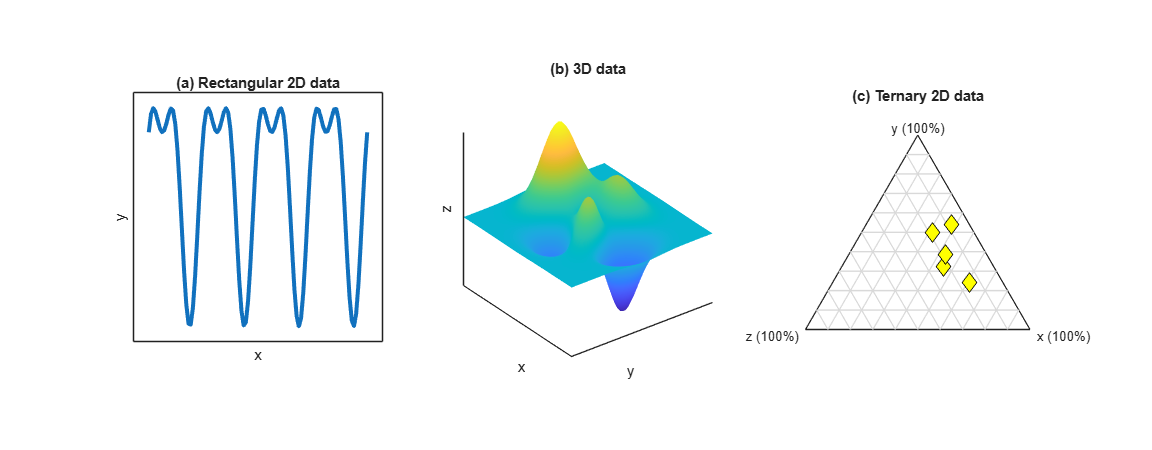

figure('units','normalized','position',[0.05 0.05 0.8 0.5])
tiledlayout('Horizontal'), nexttile
  x = linspace(-2*pi,6*pi,100); y = sin(x)+cos(x).^2;
  plot(x, y, '-', 'LineWidth',3); axis square padded
  xlabel('x'), ylabel('y')
  xticks([]), yticks([])
  title('(a) Rectangular 2D data')
nexttile
  surf(peaks,'EdgeColor','none'), axis square tight, shading interp
  title('(b) 3D data')
  xlabel('y'), ylabel('x'), zlabel('z')
  xticks([]), yticks([]), zticks([])
nexttile
  ternplot([3;6;9;8;7],[14;25;18;19;12],[20;10;13;17;19],'kd','MarkerFaceColor','y','MarkerSize',10)
  title(gca,'(c) Ternary 2D data')
  vertexlabel('x (100%)',{'y (100%)'},'z (100%)');
  v = findall(gca,'Type','Text'); [v(4:end-2).Color]=deal('none');
  gl = findall(gca,'Type','Line'); [gl(2:end).Color]=deal([0.85 0.85 0.85]);

As you may have noticed, each corner of a ternary diagram represents 100% of some variable. If you are comparing the relative abundance of three different things, then ternary diagrams become extremely useful. Geologists use ternary diagrams to show how different minerals and mineral phases relate to one another, and this information can used for classifying certain igneous rocks.

#### ====================================================================

## How to Identify Igneous Rocks

Igneous rocks are rocks that form from the solidification of magma within the Earth (called "plutonic" igneous rocks) or from the solidification of lava at the Earth surface (called "volcanic" igneous rocks). 

There are many subclasses of igneous rocks. The names given to these rocks depend on how the rock formed (i.e., from magma or from a volcanic eruption) and the ratios of specific minerals within the rocks. Geologists use ternary diagrams to plot the relative abundances of these minerals in order to identify rock samples.

#### Example

Let's say that a geologist finds a plutonic igneous rock that is 18% alkali feldspar, 52% plagioclase feldspar, and 30% quartz. Plotting this data in ternary coordinates reveals that the rock is a member of the granodiorite rock family.

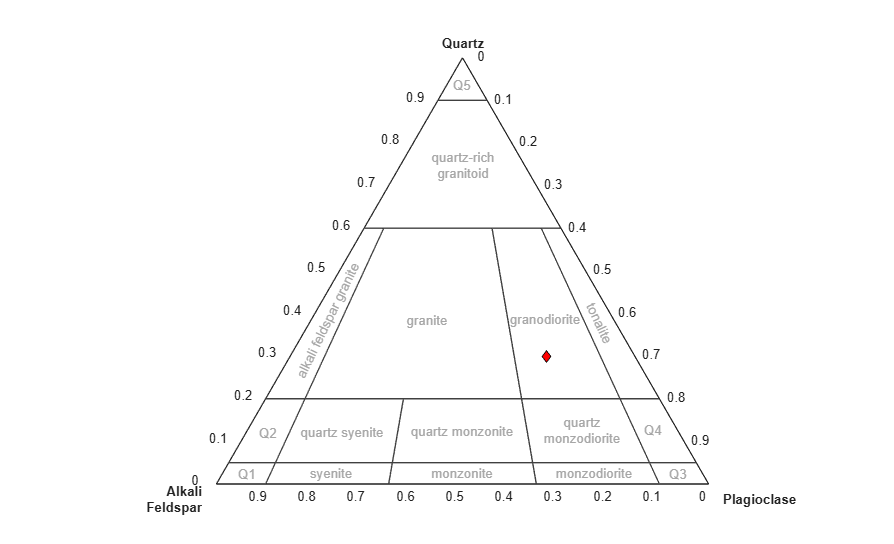

clf
figure(2)
qap_diagram('VertexLabels','on');
ternplot(18,52,30,'dk','MarkerFaceColor','r');

In contrast, if the rock was formed by volcanic processes instead of plutonic processes, then the rock would be considered a dacite:

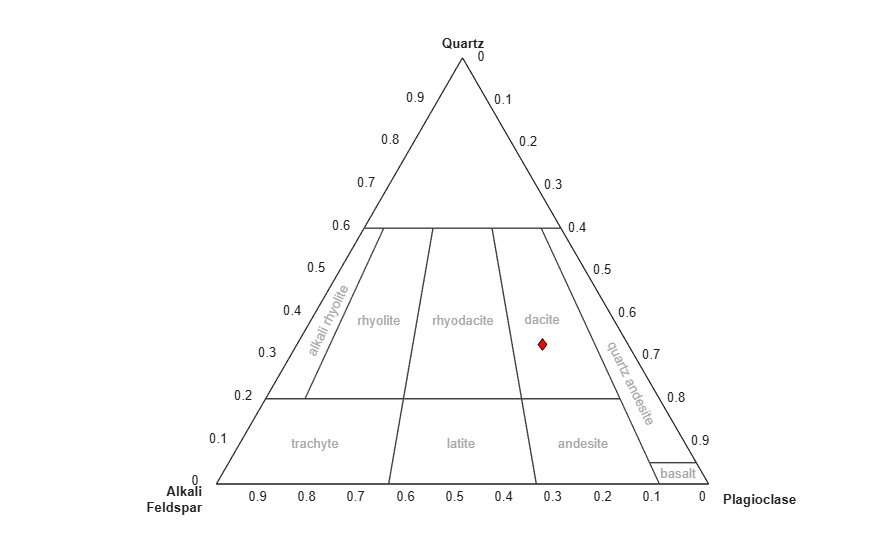

clf
figure(3)
qap_diagram('VertexLabels','on','IgneousClass','Volcanic');
ternplot(18,52,34,'dk','MarkerFaceColor','r');

### Plutonic vs. Volcanic (also known as "intrusive" and "extrusive")

But how do we distinguish whether an igneous rock was formed by plutonic or volcanic processes?

This is actually very easy (although it has nothing to do with ternary diagrams). Rocks that form by plutonic processes tend to have mineral crystals that are large enough to count with the naked eye. These rocks form deep underground where temperatures are very high and cool very slowly (sometimes for millions of years!), which gives the minerals plenty of time to grow. Granites belong to the plutonic igneous rock family. 

However, when lavas erupt at the surface, the molten material cools very rapidly and the mineral crystals cool in a geologic instant. As a result, the mineral crystals in volcanic igneous rocks tend to be microscopic in size. The rocks themselves typically look sandy or glassy. It is therefore rather rudimentary to distinguish plutonic and volcanic rocks from one other (although, admittedly, it is much easier to spot the differences in person rather than from a picture). The biggest challenge is measuring their mineral contents and determining the specific identity of the rock by consulting a ternary diagram.

#### ====================================================================

# **Practice Identifying Igneous Rocks**

Select from the drop-down menus below to examine various igneous rocks and learn how to identify them!

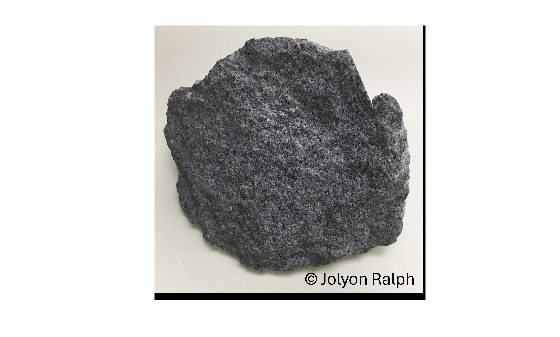

I='1';
function [type,anti_type] = inOex(s)
%Intrusive- ("plutonic") or volcanic- ("extrusive") type igneous rocks
  switch s
    case 'plutonic'
      type='plutonic'; anti_type='volcanic';
    case 'volcanic'
      type='volcanic'; anti_type='plutonic';
  end
end
switch I
  case 'N/A'
    i_file = [];
  case '1'
    i_file = 'andesite.png'; % ✅
    [i_type,anti_type] = inOex('volcanic');
  case '2'
    i_file = 'tonalite.png'; % ✅
    [i_type,anti_type] = inOex('plutonic');
  case '3'
    i_file = 'dacite.png'; % ✅
    [i_type,anti_type] = inOex('volcanic');    
  case '4'
    i_file = 'granite.png'; % ✅
    [i_type,anti_type] = inOex('plutonic');
  case '5'
    i_file = 'granodiorite.png'; % ✅
    [i_type,anti_type] = inOex('plutonic');
  case '6'
    i_file = 'syenite.png'; % ✅
    [i_type,anti_type] = inOex('plutonic');
  case '7'
    i_file = 'rhyolite.png'; % ✅
    [i_type,anti_type] = inOex('volcanic');
end
clf
if ~isempty(i_file)
  imshow(['./assets/' i_file])
end

#### ====================================================================

#### Is this rock plutonic or volcanic?

r_type="1";
switch r_type
  case '1'
    go_ahead = false;
  case '2'
    if strcmpi(i_type,'Plutonic')
      go_ahead = true;
      fprintf('Great job! The rock in the picture is plutonic! Go ahead and proceed to the next prompt.\n')
    else
      go_ahead = false;
      fprintf('Oops, not quite. This rock is actually volcanic! A general rule-of-thumb is that volcanic rocks do not have large crystals. Please modify the selection before proceeding.\n')
    end
  case '3'
    if strcmpi(i_type,'Volcanic')
      go_ahead = true;
      fprintf('Great job! The rock in the picture is volcanic! Go ahead and proceed to the next prompt.\n')
    else
      go_ahead = false;
      fprintf('Oops, not quite. This rock is actually plutonic! A general rule-of-thumb is that volcanic rocks do not have large crystals. Please modify the selection before proceeding.\n')
    end
end

#### ====================================================================

#### Plot the mineral data in ternary coordinates

Let's say that you measured the mineral contents of this rock and a few others like it. You then plot the data in the ternary diagram below.

function plot_plutonic_ternary(A,P,Q)
  clf
  qap_diagram('IgneousClass','Plutonic','VertexLabels','on');
  ternplot(A,P,Q,'dk','MarkerFaceColor','r')
end
function plot_volcanic_ternary(A,P,Q)
  clf
  qap_diagram('IgneousClass','Volcanic','VertexLabels','on');
  ternplot(A,P,Q,'dk','MarkerFaceColor','r')
end
if go_ahead
  switch i_file
    case 'andesite.png'
      % Andesite: 0-20% quartz, >65% plagioclase
      A=[15 30 10 15];
      P=[83 75 80 70];
      Q=[ 5 5 10 15];
      plot_volcanic_ternary(A,P,Q)
    case 'dacite.png'
      % Dacite: >20% quartz, Kspar:Plag < 0.5 (at least twice as much plag
      % as kspar)
      A=[23 18 20 21];
      P=[56 56 50 44];
      Q=[20 25 30 35];
      plot_volcanic_ternary(A,P,Q)
    case 'granite.png'
      % Granite: 20-60% quartz, 35-90% feldspars are alkali
      A=[50 35 35 33];
      P=[10 17 17 10];
      Q=[40 48 25 33];
      plot_plutonic_ternary(A,P,Q)
    case 'granodiorite.png'
      % Granodiorite: 20-60% quartz, 65-90% of feldspars are plagioclase
      % Data from Atherton & Sanderson (1987)
      % for the Cordillera Blanca "ridge granodiorite"
      A = [13.5;  8.8; 10.2; 15.4; 21.3; 17.6];
      P = [51.2; 43.8; 47.7; 39.1; 40.2; 56.9];
      Q = [22.7; 18.6; 29.5; 36.9; 35.4; 25.4];
      plot_plutonic_ternary(A,P,Q)
    case 'rhyolite.png'
      % Rhyolite: >20% quartz, feldspars 40-90%
      A=[49 34 36 46];
      P=[11 18 19 15];
      Q=[42 45 23 32];
      plot_volcanic_ternary(A,P,Q)
    case 'syenite.png'
      % Syenite: <5% quartz, 65-90% alkali feldspar:plagioclase ratio
      A=[72 72 55 63];
      P=[24 36 20 11];
      Q=[ 4  7  3  2];
      plot_plutonic_ternary(A,P,Q)
    case 'tonalite.png'
      % Tonalite: 20-60% quartz, 40-80% feldspar where plagioclase is >90%
      % of the total feldspar content
      A=[ 0  2  1  3];
      P=[69 73 60 62];
      Q=[31 25 39 55];
      plot_plutonic_ternary(A,P,Q)
  end
end

#### ====================================================================

#### Identify the rock from the ternary diagram

id="N/A";
if strcmpi(id,'N/A')
  % Do nothing
elseif strcmpi(id,i_file(1:end-4))
  fprintf('That''s exactly right! The rock in the image is %s. Can you guess its %s equivalent?\n',upper(id),anti_type);
else
  fprintf('Sorry, that isn''t quite right. Please try again.\n');
end

#### ====================================================================

#### Can you guess its equivalent based on previous information?

(Hint: scroll back up to the example charts)

id="N/A";

switch id
  case 'N/A'
    % Do nothing
  case {'basalt','tonalite'}
    % Red herrings
    fprintf('Nope, not quite. Please try again.\n')
  case 'monzodiorite'
    if strcmpi('andesite',i_file(1:end-4))
      fprintf('That''s exactly right! %s is the %s equivalent of %s.\n',upper(id),anti_type,upper(i_file(1:end-4)));
    else
      fprintf('Nope, not quite. Please try again.\n')
    end
  case 'quartz andesite'
    if strcmpi('tonalite',i_file(1:end-4))
      fprintf('That''s exactly right! %s is the %s equivalent of %s.\n',upper(id),anti_type,upper(i_file(1:end-4)));
    else
      fprintf('Nope, not quite. Please try again.\n');
    end
  case 'granodiorite'
    if strcmpi('dacite',i_file(1:end-4))
      fprintf('That''s exactly right! %s is the %s equivalent of %s.\n',upper(id),anti_type,upper(i_file(1:end-4)));
    else
      fprintf('Nope, not quite. Please try again.\n');
    end
  case 'dacite'
    if strcmpi('granodiorite',i_file(1:end-4))
      fprintf('That''s exactly right! %s is the %s equivalent of %s.\n',upper(id),anti_type,upper(i_file(1:end-4)));
    else
      fprintf('Nope, not quite. Please try again.\n');
    end
  case 'rhyolite'
    if strcmpi('granite',i_file(1:end-4))
      fprintf('That''s exactly right! %s is the %s equivalent of %s.\n',upper(id),anti_type,upper(i_file(1:end-4)));
    else
      fprintf('Nope, not quite. Please try again.\n');
    end
  case 'trachyte'
    if strcmpi('syenite',i_file(1:end-4))
      fprintf('That''s exactly right! %s is the %s equivalent of %s.\n',upper(id),anti_type,upper(i_file(1:end-4)));
    else
      fprintf('Nope, not quite. Please try again.\n');
    end
  case 'granite'
    if strcmpi('rhyolite',i_file(1:end-4))
      fprintf('That''s exactly right! %s is the %s equivalent of %s.\n',upper(id),anti_type,upper(i_file(1:end-4)));
    else
      fprintf('Nope, not quite. Please try again.\n');
    end
end

#### ====================================================================

# **Bonus: Dynamically adjust Q-A-P ratios to see how it affects the rock type**

You may have noticed that the ternary diagrams used for identifying igneous rocks depend on the amount of **quartz** (**Q**), **alkali feldspar** (**A**), and **plagioclase feldspar** (**P**) in the sample. As such, geologists frequently refer to these visualizations as Q-A-P diagrams (hence the name of this repository's GitHub page).

Use the controls below to see how changing the ratios of Q, A, and P affects the rock classification. 

igneous_class="N/A";
N_quartz = 28;
N_kspar  = 17;
N_plag   = 55;
N_total = N_quartz + N_kspar + N_plag;
Qnorm = 100*N_quartz / N_total;
Anorm = 100*N_kspar  / N_total;
Pnorm = 100*N_plag   / N_total;
if strcmpi(igneous_class,'N/A')
  % Do nothing
else
  fprintf('Normalized ratio: %d%% Quartz, %d%% Alkali feldspar, %d%% Plagioclase.\n',...
    round(Qnorm), round(Anorm), round(Pnorm))
end
clf
switch igneous_class
  case 'N/A'
    % Do nothing
  case 'Plutonic'
    plot_plutonic_ternary(Anorm,Pnorm,Qnorm);
  case 'Volcanic'
    plot_volcanic_ternary(Anorm,Pnorm,Qnorm);
end

### ====================================================================

### References

`Carl Sandrock (2015). alchemyst/ternplot (https://github.com/alchemyst/ternplot), GitHub. Retrieved October 6, 2026.`

#### Acknowledgments

Creating ternary diagrams in MATLAB is possible thanks to the efforts of Carl Sandrock, who developed the `alchemyst/ternplot` package on the File Exchange. To make visualizing geologic ternary diagrams easier, I built upon the work of Mr. Sandrock and released my own package on the File Exchange called QAP Diagrams (QAP standing for "Quartz-Alkali Feldspar-Plagioclase"). Both of these packages were used in the writing of this Live Script. I also thank the Smithsonian Institution, Jolyon Ralph, Andrea Oppicelli, Marek Zalipski, Rui Nunes, RJ Martin, and the [`Mindat.org`](http://mindat.org) contributors for the igneous rock images used in the interactive demonstration. I would also like to give special thanks to Michael R. Ackerson who inspired me several years ago to learn about igneous rocks.